%load data
rna = readtable('rna_sel_features_107genes.xlsx', 'ReadRowNames',true);
save('rna.mat', 'rna')

mirna = readtable('mirna_sel_features_61genes.xlsx','ReadRowNames',true);
save('mirna.mat', 'mirna')

cnv = readtable('cnv_sel_features_166genes.xlsx','ReadRowNames',true);
save('cnv.mat', 'cnv')

mutation = readtable('mutation_sel_features_14genes.xlsx','ReadRowNames',true);
save('mutation.mat', 'mutation')

%methylation = readtable('methylation_sorted_out.csv','ReadRowNames',true);
%save('methylation.mat', 'methylation')

protein = readtable('protein_sel_features_19genes.xlsx','ReadRowNames',true);
save('protein.mat', 'protein')

clinical = readtable('Clin_feat_for_NN.xlsx','ReadRowNames',true);

save('clinical.mat', 'clinical');

# **Lung Adenocarcinoma: Patient survival prediction.**

**A cancer patient data set containing 198 patient samples and approx 22k genes or features will be used to train a model to predict patient survival into three possible classes: alive, alive_relapse, relapse_dead.**

%load Data
load('cnv.mat');
load('mirna.mat');
load('rna.mat');
load('protein.mat');
load('mutation.mat');
%load('response.mat', 'T');
load('clinical.mat');
T= xlsread('response.xlsx');

Error using xlsread (line 136)
XLSREAD unable to open file 'response.xlsx'.
File 'D:\DATA\matlab_data\OmicsProject\6omics_vidhi_mam\Neural_net_4_6omics\STEP_2_NeuralNet\response.xlsx' not found.

%protein1=protein;
%[d,t1] = xlsread('clinical_sorted_out.xlsx');
%response = categorical(d(:,2));
%protein.class = response;
%feature_table = cnv;

cnv = (table2array(cnv))';
rna = (table2array(rna))';
mirna = (table2array(mirna))';
protein = (table2array(protein))';
mutation = (table2array(mutation))';
clinical = (table2array(clinical))';
%response= (table2array(response))';
x= {cnv; mirna; rna; protein; mutation; clinical};
%T=response;
%T=grp2idx(response);
%T = protein.class';
% 
% % === train the network
% [net,tr] = train(net,P,T)

%x = P1;
t = T';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
rng(1);
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = [14 8];
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(trainFcn);
%view(net)
% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 75/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 10/100;

%set crossentropy as performance eval
net.performFcn = 'crossentropy';
net.performParam.regularization = 0.4;
net.performParam.normalization = 'none';

%net = feedforwardnet(10,trainFcn);
net.numinputs = 6;
net.inputConnect = [1 1 1 1 1 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputConnect = [1 1 1 1 1 1; 0 0 0 0 0 0];
% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
y=cell2mat(y);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0816

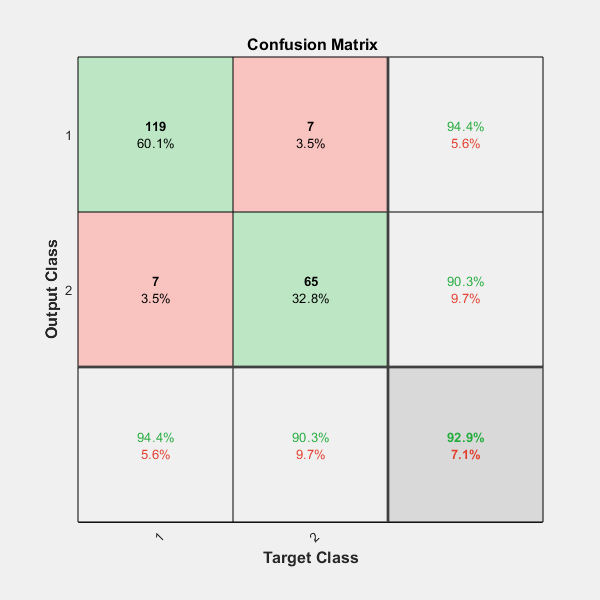

tind = vec2ind(t);
yind = vec2ind(y);
%tind=t;
%yind=y;
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
%view(net)

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)

Error using confusion (line 43)
Targets and outputs have different dimensions.

Error in plotconfusion>update_plot (line 487)
    [c,cm] = confusion(t,y);

Error in plotconfusion (

%analysing net performance
O = sim(net,x);
O=cell2mat(O);
figure()
plotconfusion(T,O);